# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# SIMULATION OF OFDM WITH MATLAB

## Introduction

This last live script discuss channel effects and their estimation and compensation for OFDM.

## Index

- OFDM basics and implementation, frame structure, guards and cyclic prefix.

- LTE (4G) Particularization.

- 5G Particularization.

- Channel effects and their estimation and compesation for OFDM. 

## 4. CHANNEL EFFECTS

We know that the OFDM receiver consists of undoing the IFFT that was done during transmission, meaning we have to perform an FFT, like it is shown in the next image.

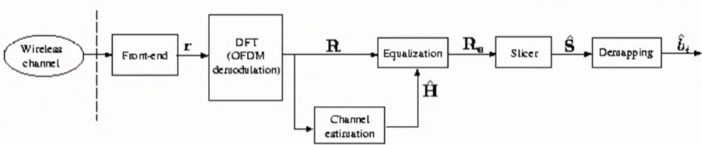

Thus, the OFDM Receiver responds to the following equation: 


$$\[
Y[k] = \sum_{n=0}^{N-1} y[n] \, e^{-j 2\pi \frac{kn}{N}}, \quad k = 0, 1, \dots, N-1
\]$$


Where:

- y[n]: Time-domain received OFDM symbol (after CP removal)

- Y[k]: Received frequency-domain symbol (subcarrier kkk)

- N: Number of subcarriers

But, we must take into account that our OFDM signal will pass through a channel, so at the input of the receiver, we will receive the convolution between the transmitted signal and the channel (*r*). If we then apply the FFT to this, we will obtain the transmitted signal multiplied by the frequency response of our channel (*R*). If we do this per subcarrier, which is possible in OFDM, we get the next formula:


$$R_k =H_k \;S_k +W_{k\;} \;,\;0\le k\le N-1$$


$H_k$ is the response of the channel in the *k *subcarrier. 

$S_k$ symbol that we have sent in the subcarrier k.

$W_k$ is the noise for the subcarrier k. 

So, we are interested in the transmitted symbol ($S_k$), and to obtain this value, we need to remove the effect of the channel ($H_k$), and for doing that, we need to estimate the channel and then compensatate it, this is what we call "Channel equalization" (getting rid of the channel effects). 

### 4.1 Techniques for estimating the channel

There are two different techniques to estimate the channel: 

- **Data-Aided (PSA)**: this means Pilot Symbol Aided with known reference signals. It has loss of data rate. 

- **Decision-Directed (NPSA):** this is a technique without pilots, but it has error propagation.

We are going to use the first one, PSA. This means that we are going to send a sequence of known samples, called pilots, and we will use these pilots to estimate the channel. Obviously, since we are using some time-frequency slots to estimate the channel, we are not using them for sending data information, and therefore, we have a loss of data rate, but this is the price we have to pay. 

### 4.2 Placement of pilots 

The next step we have to do is to determine where to place these pilots. 

We need to estimate the channel in time and frequency. Therefore, if we look at the frequency-time grid that we have in OFDM, we need to estimate the channel for each OFDM Symbol (with a time duration *Lp*), in all the frequencies. 

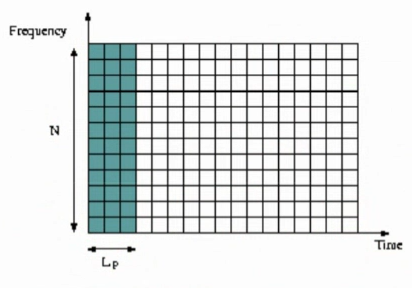

So, for sending the pilots, we need to make some assumptions. One could be the one presented in the image below. We can send the pilots represented in green, assuming that in each time slot, the channels stays constant in frequency between the pilots. This is really useful if the channel varies very quickly along the time, which is why we are sending pilots for one frequency but all the time. 

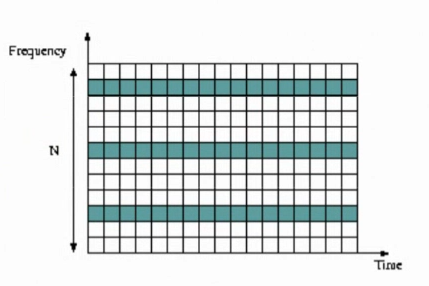

In order to decide the placement of pilots, we can choose between different schemes, depending on the particular needs of our situation and how the channel varies in time and frequency. In the next image, we can see different patterns we can choose for sending the pilots. Let's analyze the different situations. 

- **Frequency Sweeping**: we send the pilots in all the frequencies of one time slot. We assume that the channel stays constant for a time, after which we send again the column of pilots, however it varies a lot in frequency. 

- **Rectangular**: in this case, we send pilots in some times and frequencies, and we assume that our channel doesn't change in *v1* and *v2*. This is the most usual situation.

- **Hexagonal**: this one is similar to the rectangular one, but we vary where to place the pilots from time to time, instead of always placing them in the same frequencies. 

- **Rectang. Linear-Increas:** this last one is a variation of the rectangular one, in which the pilots are placed in diagonal through the frequencies. 

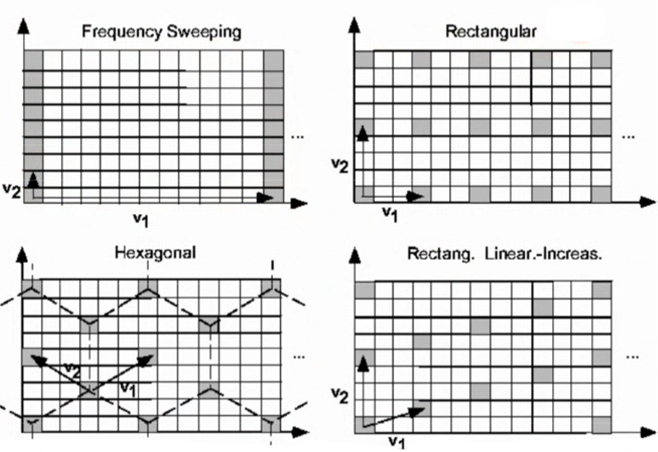

We are going to implement the "Frequency Sweeping" pattern, therefore, all the data subcarriers will carry pilots in the first OFDM symbol, with that symbol we will make the estiamation of the channel assuming it's going to be constant. We start defining the parameters:

N_OFDM=2048;
Ng=1/8*N_OFDM;

P_ampl=1; %Pilot's amplitude
P_ampl_10=10; %Bigger amplitude for the pilots to compare it with the data signal
fg_1=171;
fg_2=172;
Fs=20; %MHz

N_OFDM_ef=N_OFDM-fg_1-fg_2; 
N_symb=100; 
n_samples=N_symb.*N_OFDM_ef; 

 

We define one signal for the pilots with amplitude 1, and another one for the pilots with amplitude 10.

signal_10=zeros(1,N_symb*(N_OFDM+Ng));     
signal=zeros(1,N_symb*(N_OFDM+Ng));     

for (symb=1:N_symb)  %In the first symbol, everything are pilots. 

    i=sign(rand(1,N_OFDM_ef)-0.5);
    q=sign(rand(1,N_OFDM_ef)-0.5);
    qpsk=i+j*q;

    qpsk_ini=zeros(1,N_OFDM);
    qpsk_ini_10=zeros(1,N_OFDM);

    if (symb==1) %All the carriers are pilots.
       % pilots=P_ampl*randn(1,N_OFDM-fg_2-fg_1);
        pilots=P_ampl*qpsk;
        
        qpsk_ini(fg_1+1:N_OFDM-fg_2)=pilots;

        pilots10=P_ampl_10*pilots;
        qpsk_ini_10(fg_1+1:N_OFDM-fg_2)=pilots10;
    else
        qpsk_ini(fg_1+1:N_OFDM-fg_2)=qpsk;
        qpsk_ini_10(fg_1+1:N_OFDM-fg_2)=qpsk;
    end
    

    ofdm=ifft(qpsk_ini,N_OFDM);
    ofdm=[ofdm(N_OFDM-Ng+1:N_OFDM),ofdm];

    ofdm_10=ifft(qpsk_ini_10,N_OFDM);
    ofdm_10=[ofdm_10(N_OFDM-Ng+1:N_OFDM),ofdm_10];

    signal(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm;
    signal_10(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm_10;


end 

Now, we represent the first symbol where all are pilots. However, what we see is the spectrum of a QPSK signal, so it's difficult to notice the difference between both cases (high and low amplitude) since we only have pilots in the first symbol.  

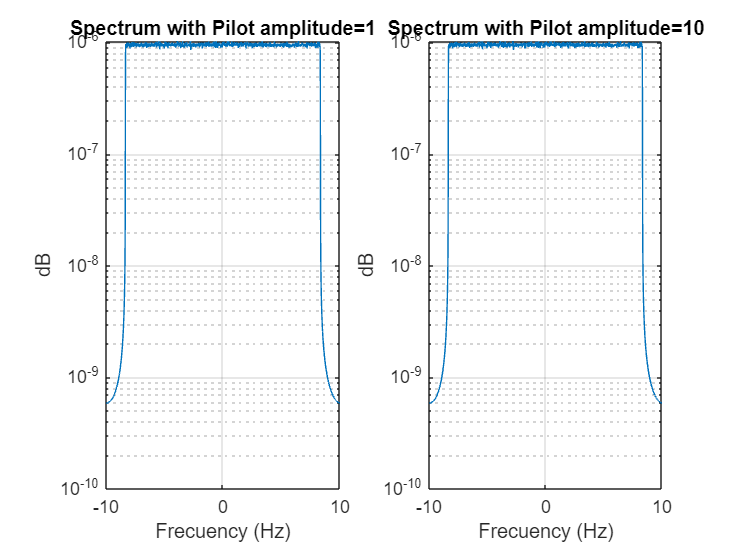

[p,f] = pspectrum(signal);
[p_10,f_10] = pspectrum(signal);
new_f=f./pi*Fs/2;
new_f_10=f_10./pi*Fs/2;


subplot(1,2,1)
semilogy(new_f,fftshift(p))
grid on
title('Spectrum with Pilot amplitude=1')
xlabel("Frecuency (Hz)")
ylabel('dB')

subplot(1,2,2)
semilogy(new_f_10,fftshift(p_10))
grid on
title('Spectrum with Pilot amplitude=10')
xlabel("Frecuency (Hz)")
ylabel('dB') 

As next step, we are going to represent the signal before applying the IFFT to see every OFDM symbol, verifying how the first one, contains a QPSK that represents the pilots. 

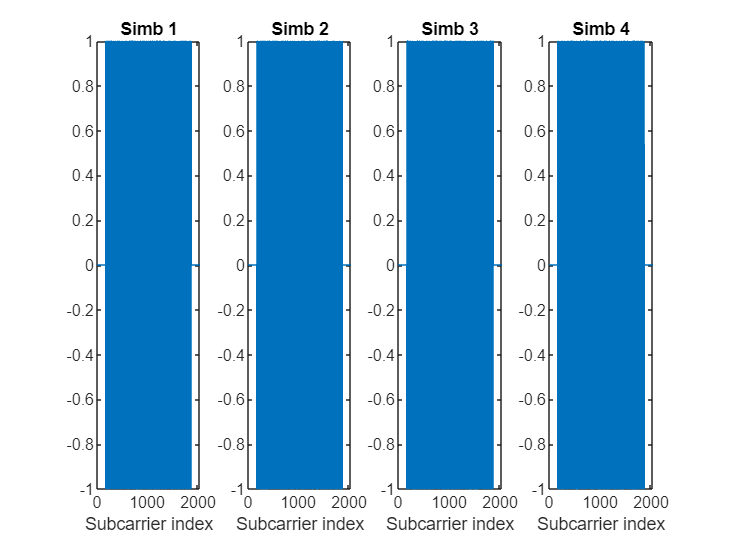

N_symb_to_represent_before_ifft=4;

qpsk_ini_all = zeros(N_OFDM, N_symb_to_represent_before_ifft); 

for (symb = 1:N_symb_to_represent_before_ifft)  
    i = sign(rand(1, N_OFDM_ef) - 0.5);
    q = sign(rand(1, N_OFDM_ef) - 0.5);
    qpsk = i + 1j * q; 

    qpsk_ini = zeros(1, N_OFDM);
    
    if (symb == 1) 
        qpsk_ini(fg_1 + 1:N_OFDM - fg_2) = pilots;
    else
        qpsk_ini(fg_1 + 1:N_OFDM - fg_2) = qpsk;
    end
    
    qpsk_ini_all(:, symb) = qpsk_ini.'; 

    ofdm = ifft(qpsk_ini, N_OFDM);
    ofdm = [ofdm(N_OFDM - Ng + 1:N_OFDM), ofdm];

end

figure (5); 

for symb = 1:N_symb_to_represent_before_ifft
    subplot(1,N_symb_to_represent_before_ifft,symb)
    plot(real(qpsk_ini_all(:, symb)), 'DisplayName', ['Símbolo ' num2str(symb)]); 
    title(['Simb ', num2str(symb)]);
    xlabel('Subcarrier index');
   
end

We are going to zoom in; previously, we could see the 2048 subcarriers of each OFDM symbol with their respective values. In the first symbol, all are pilots with a QPSK modulation, while in the rest we see the data QPSK signal. To take a closer look, we will represent only the first and second symbols. Then, since the initial guard band, as we have established, consists of 171 subcarriers, we will represent from subcarrier 172 to 200. We can clearly see that, for the pilots in the first OFDM symbol, and in the rest of the symbols, the amplitudes vary from -1 to 1, as expected, since we are working with QPSK modulation

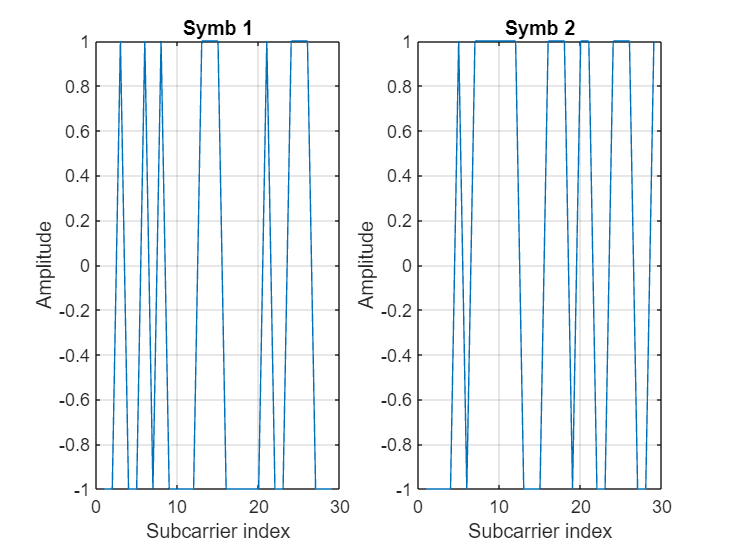

figure (6); 
for symb = 1:2
    subplot(1,2,symb)
    signal_to_represent=real(qpsk_ini_all(:, symb));
    plot(signal_to_represent(172:200), 'DisplayName', ['Símbolo ' num2str(symb)]); % Parte real
    title(['Symb ', num2str(symb)]);
    xlabel('Subcarrier index');
    ylabel('Amplitude')
    grid on
   
end

Now, we are going to represent the spectrum for the three first symbols, again since the pilots are QPSK symbols, we won't see any difference with the data signal, regarding the shape of the spectrum. However, to see the difference between pilots and data, we are going to use an amplitude of 100 for the pilots, this way we can clearly see how the spectrum of the first symbol, that corresponds to the pilots, has a higher amplitud than the rest of them.  

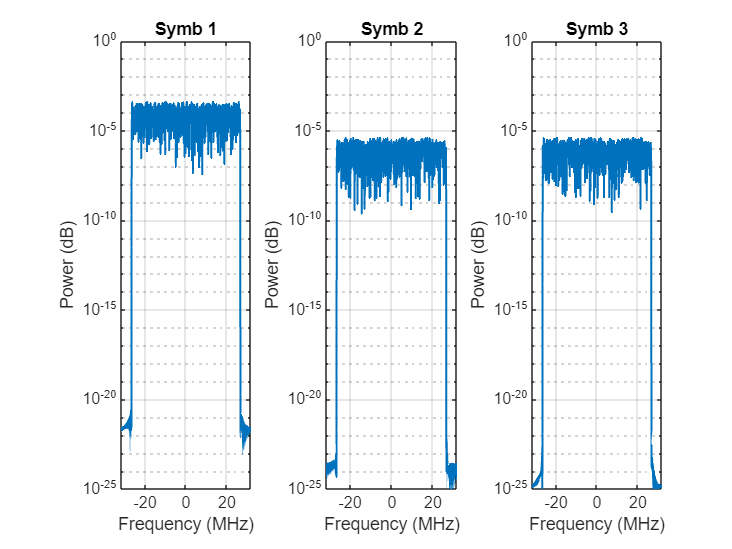

espectrums = [];

N_symb_to_represent=3;

for symb = 1:N_symb_to_represent  

    i = sign(rand(1, N_OFDM_ef) - 0.5);
    q = sign(rand(1, N_OFDM_ef) - 0.5);
    qpsk = i + 1j * q;

    qpsk_ini = zeros(1, N_OFDM);
   

    if (symb == 1) % Pilots
        qpsk_ini(fg_1+1:N_OFDM-fg_2) = P_ampl_10*pilots; 
     
    else
        qpsk_ini(fg_1+1:N_OFDM-fg_2) = qpsk;
        
    end

    ofdm = ifft(qpsk_ini, N_OFDM);
    ofdm = [ofdm(N_OFDM-Ng+1:N_OFDM), ofdm];


    signal100(1, (symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng)) = ofdm;
 
    %Calculating the spectrum
    [p, f] = pspectrum(ofdm, Fs);

    
    espectrums(:, symb) = p;    % Each symbol is the spectrum of one symbol

    new_f = f ./ pi * Fs / 2;

    figure(1); 
    subplot(1, N_symb_to_represent, symb);  
    semilogy(new_f, fftshift(p), 'LineWidth', 1);
    xlabel('Frequency (MHz)');
    ylabel('Power (dB)');
    ylim([1e-25, 1]);
    title(['Symb ', num2str(symb)]);
    grid on;

  
end 

Finally, we can represent the signal in time, using as x-axis, first the time in microseconds, and then the number of subcarriers, to see how the first 2048 subcarriers, or 115 microseconds, correspond to the the first symbol where all the information consists of pilots. 

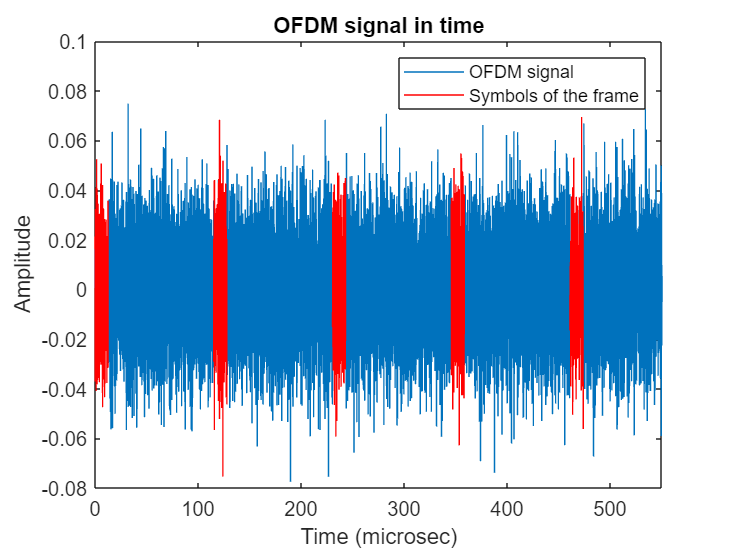

figure
time=(0:1/Fs:((N_symb)*(N_OFDM+Ng))/Fs-1/Fs); 
plot(time,real(signal))
hold on
for (symb=1:N_symb)   
    plot( time( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
end
xlim([0 550])
xlabel('Time (microsec)')
ylabel('Amplitude')
title('OFDM signal in time')
legend('OFDM signal','Symbols of the frame') 

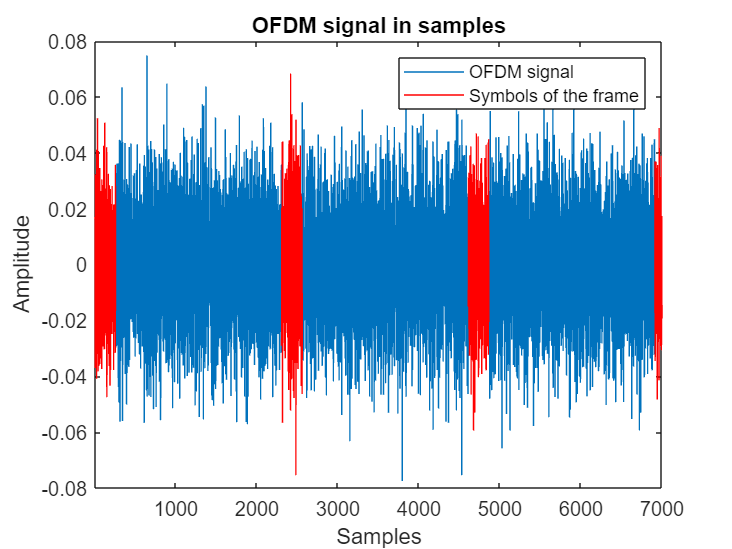

figure
samples=(0:1:((N_symb)*(N_OFDM+Ng))-1); 
plot(samples,real(signal))
hold on
for (symb=1:N_symb)   
    plot(samples( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
end
xlim([1 7000])
xlabel('Samples')
ylabel('Amplitude')
title('OFDM signal in samples')
legend('OFDM signal','Symbols of the frame') 

We see that the first OFDM symbol, which consists of 2048 samples, only contains pilots with constant amplitude in frequency, so it makes sense that the received OFDM signal is what we observe. Meanwhile, the next symbol, which will start at sample *2048 + 171 (the first guard band) = 2219*, begins to show the OFDM signal without pilots.

It is clear that is difficult to distinguish the first OFDM symbol where all the subcarriers are pilots from the rest of the symbols that carry some data. In order to make this easier, we are going to repeat the previous process, but using the signal that as pilots contains a QPSK signal but with amplitude 10. Since this amplitude is a lot higher that the one that the data signal has, we will se how only the first symbol contains pilots, while the rest are data symbols.

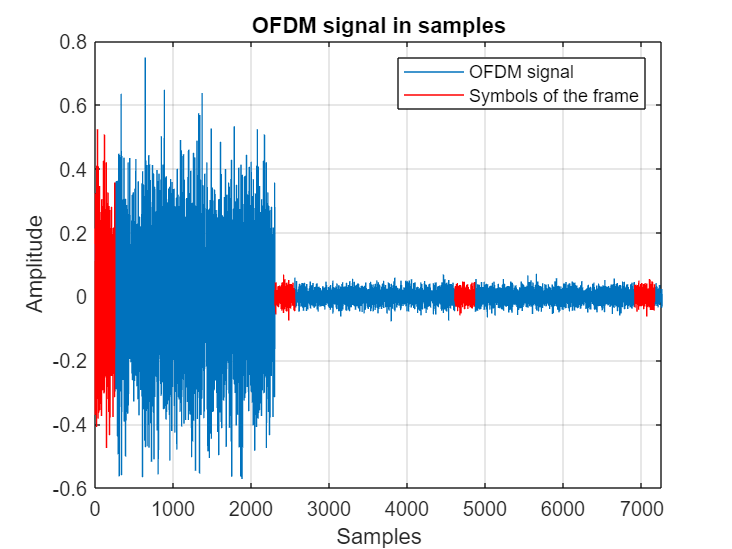

figure
samples=(0:1:((N_symb)*(N_OFDM+Ng))-1); 
plot(samples,real(signal_10))
hold on
for (symb=1:N_symb)   
    plot(samples( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal_10( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
end
xlim([1 7000])
grid on
xlabel('Samples')
ylabel('Amplitude')
title('OFDM signal in samples') 
legend('OFDM signal','Symbols of the frame') %Para el caso de pilotos de amplitud 100, pues dominarian sobre toda las señal, por lo que solo vemos pilotos

 Clearly, as we were expecting, the first 2048 subcarriers corresponding to the first OFDM symbol have an amplitude higher than the rest of the symbols, despite being also a QSPK modulation. This is because only the first symbol contains the pilots to estimate the channel.

### 4.3 Channel estimation on the pilot positions:

We are going to use the Least Squeares (LS) criterion for channel estimation, that minimises the error between measuments and the linear model. 

We are going to use the next formula:


$$H_p =P^{-1} \textrm{Rp}$$


$H_p$ is the channel estimated at pilot positions ($\left.K_p \right)$.

$P$ is the matrix with the known pilot values.

$R_p$ is the received symbols in pilot positions ($\left.K_p \right)$.

We want to estimate the channel, which means that we want to discover $H_p$.

In this case, ***Rp*** would be the first symbol we receive. Therefore,*** Rp*** is a vector with the size of the number of subcarriers, because we have only inserted pilots in this first symbol. Moreover, since in this section we want to estimate the channel and recover the transmited signal, we are going to start sending our signal through a channel ***h ***that is going to only have 2 taps, 1 and 0.5. Then we will use the function "filter" to generate the received signal "***r***" , that corresponds to the signal that has been sent through the channel. To estimate the channel, we are going to loop through all symbols, and for each one we are going to extract the received symbol with the cyclic prefix removed. Then, we will apply the *FFT* over this symbol, to make the OFDM demodulation, and if we are in the iteration corresponding to the first symbol, we will estimate the channel using the pilots that this symbol contais, obviously removing first the guard bands*** fg_1*** and ***fg_2*** to use only the pilots sent, applyng the formula ***Rp/pilots=est_H = q(fg_1 + 1 : N_OFDM - fg_2) / pilots.***

For the rest of the OFDM symbols, that contain the data sent, we will use the estimated channel ***est_H*** to recovery the transmitted signal, using the zero forcing method, ***q_corr (transmitted signal) = q (received signal) / est_H***. 

Therefore, since the transmitted signal was a QPSK signal, once we "correct" or estimate the receive signal using the Zero Forcing, we should get a QPSK signal in the receiver side. This is perfectly obtained for all the symbols, as we can see in the constelation represented below.

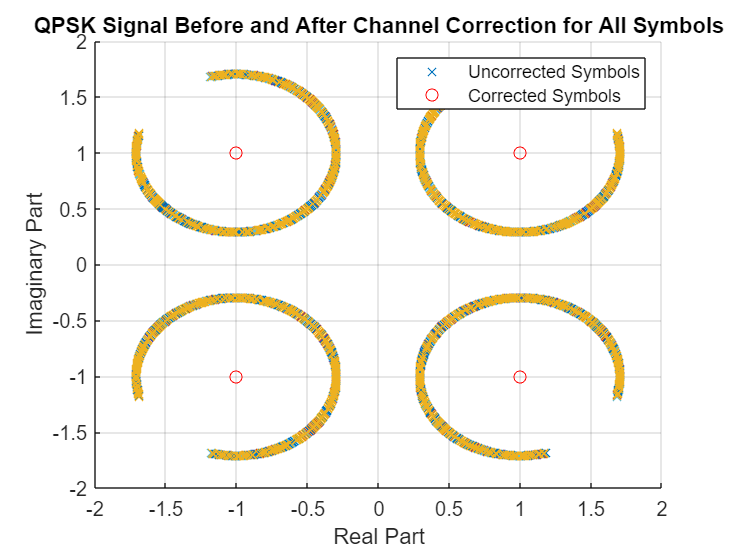

% Define channel
h = [1 0.5];

% Transmit signal through the channel
r = filter(h, 1, signal);

% Initialize figure for plotting
figure;
hold on;
title(['QPSK Signal Before and After' ...
    ' Channel Correction for All Symbols']);
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;

% Loop through all symbols to perform channel estimation and correction
for ind = 1:N_symb
    % Extract received symbol with cyclic prefix removed
    recibida = r((ind - 1) * (N_OFDM + Ng) + 1 + Ng : ind * (N_OFDM + Ng));
    q = fft(recibida);

    if ind == 1
        % Estimate channel on the first symbol (all pilots)
        est_H = q(fg_1 + 1 : N_OFDM - fg_2) ./ pilots;
    end
    
    % Apply channel correction
    q_corr = q(fg_1 + 1 : N_OFDM - fg_2) ./ est_H;

    % Plot uncorrected and corrected symbols
    plot(q(fg_1 + 1 : N_OFDM - fg_2), 'x');           % Uncorrected
    plot(q_corr, 'or');                               % Corrected
end

legend('Uncorrected Symbols', 'Corrected Symbols');
hold off;

Before finishing this section, we can make some more tests to verify how we are properly doing the channel estimation. 

First, we can represent the signal received "***r***" , once the transmitted signal has been sent through the channel, to see the effect that this channel causes over the trasmitted signal:

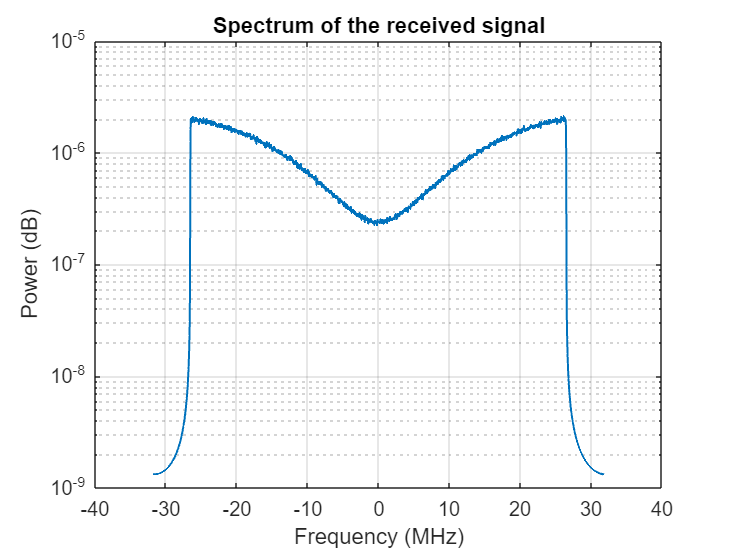

%Calculate the spectrum for the received signal. 
[p2, f2] = pspectrum(r, Fs);

new_f2 = f2 ./ pi * Fs / 2;

figure(); 
semilogy(new_f2, fftshift(p2), 'LineWidth', 1);
xlabel('Frequency (MHz)');
ylabel('Power (dB)');
title("Spectrum of the received signal")
grid on;

Finally, we can represent the spectrum of the original channel "***h***", and the spectrum of the estimated channel "***H_est***", just to verify that both of them are exactly the same, which is why we have been able to previously obtain such a good constelation after estimating the channel and the sent signal. 

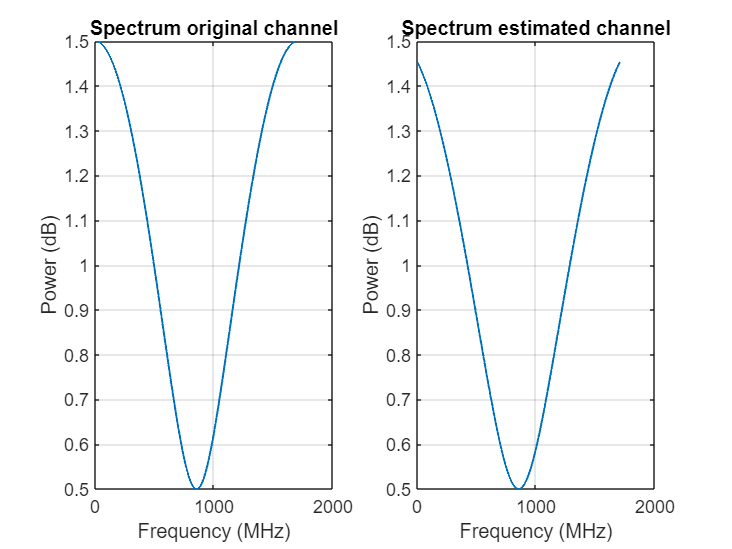

figure(); 
subplot(1,2,1)

p=fft(h,length(est_H)); %Spectrum of the original channel
plot((abs(p)), 'LineWidth', 1); 
grid on
xlabel('Frequency (MHz)'); 
ylabel('Power (dB)');
title("Spectrum original channel")

subplot(1,2,2)
plot((abs(est_H)) , 'LineWidth', 1); %Spectrum of the estimated channel
grid on
xlabel('Frequency (MHz)'); 
ylabel('Power (dB)');
title("Spectrum estimated channel")